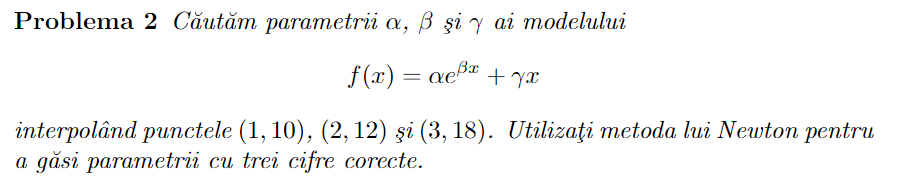

ea = 0;
er = 1e-3;

x0 = [10, 1, -6]';

f = @(x) [x(1)*exp(x(2))+x(3)-10; x(1)*exp(2*x(2))+2*x(3)-12; x(1)*exp(3*x(2))+3*x(3)-18];
fjacob = @(x) [exp(x(2)), x(1)*exp(x(2)), 1; exp(2*x(2)), 2*x(1)*exp(2*x(2)), 2; exp(3*x(2)), 3*x(1)*exp(3*x(2)), 3];

z = Newton(f, fjacob, x0, ea, er);
alpha = z(1)

alpha = 10.6667

beta = z(2)

beta = 0.4055

gamma = z(3)

gamma = -6.0000

% f, fd - functia si derivata sa
% x0 - aproximatia initiala 
% ea, er - eroarea absoluta si eroarea relativa
% output : z - solutia aproximata

function [z, ni] = Newton(f, fd, x0, ea, er)
    maxIter = 50;
    xp = x0(:);
    for k = 1:maxIter
        xc = xp - fd(xp) \ f(xp);
        if norm(xc - xp, inf) < ea + er * abs(xc)
            z = xc; 
            ni = k;
            return
        end
        xp = xc;
    end
end